# PSET 3

# Tarun Kamath

## Problem 1: Somatic Inhibition

- So we first have to write the equations for the current in each of the dendritic and somatic compartments. However, by Kirchhoff's Current Law, we know that the current going into a junction must be equal to the current going out of a junction. Thus we can write:


$$\begin{array}{l}
\mathrm{Dendritic}:G^∗ ∗\left(V_s -V_d \right)=G_e ∗\left(V_d -E_e \right)+G_d ∗V_d \\
\mathrm{Somatic}:G_i ∗\left(-V_s \right)+G_s ∗V_s =\left(V_s -V_d \right)∗G^∗ 
\end{array}$$


2. We can simplify the above equations by solving for V_d in each of them and then setting them equal to each other:


$$\begin{array}{l}
\mathrm{Dendritic}:\\
G^∗ ∗\left(V_s -V_d \right)=G_e ∗\left(V_d -E_e \right)+G_d ∗V_d \\
=G^∗ ∗V_s -G^∗ ∗V_d =G_e ∗V_d -G_e ∗E_e +G_d ∗V_d \\
=G_e ∗V_d +G_d ∗V_d +G^∗ ∗V_d =G^∗ ∗V_s +G_e ∗E_e \\
=V_d =\frac{\left(G^∗ ∗V_s +G_e ∗E_e \right)}{G_e +G_d +G^∗ }
\end{array}$$


We can do the same thing for the somatic compartment


$$\begin{array}{l}
-G_i ∗V_s -G_s ∗V_s =\left(V_s -V_d \right)∗G^∗ \\
=G^∗ ∗V_d =\left(G^∗ +G_i +G_s \right)∗V_s \\
=V_d =\frac{\left(G^∗ +G_i +G_s \right)}{G^∗ }∗V_s 
\end{array}$$


We can think of the expression for the somatic compartment as $V_d =a∗V_s$. We can think of the expression for the dendritic compartment as $V_d =b∗V_s +c$. Thus if we equate these, then 

$V_s =\frac{c}{a-b}$ with $a=\frac{\left(G^∗ +G_i +G_s \right)}{G^∗ }$, $b=\frac{\left(G^∗ \right)}{G_e +G_d +G^∗ }\text{ }$, and $c=\frac{\left(G_e ∗E_e \right)}{G_e +G_d +G^∗ }\text{ }$. Thus we can do:


$$\begin{array}{l}
V_s =\frac{\left(\frac{\left(G_e ∗E_e \right)}{G_e +G_d +G^∗ }\right)}{\frac{\left(G^∗ +G_i +G_s \right)}{G^∗ }-\frac{G^∗ }{G_e +G_d +G^∗ }}\\
=\frac{\left(G_e ∗E_e \right)}{\frac{\left(\left(G_e +G_d +G^∗ \right)∗\left(G^∗ +G_i +G_s \right)\right)}{G^∗ }-G^∗ }\\
=\frac{\left(G_e ∗E_e ∗G^∗ \right)}{G_e ∗G^∗ +G_d ∗G^∗ +G^{∗^2 } +G_e ∗G_i +G_d ∗G_i +G_i ∗G^∗ +G_s ∗G_e +G_s ∗G_d -G^{∗^2 } }\\
=\frac{\left(G_e ∗E_e ∗G^∗ \right)}{G^∗ ∗G_d +G_s ∗G_d +G_s ∗G^∗ +G_e ∗\left(G^∗ +G_i +G_s \right)+G_i ∗\left(G_d +G^∗ \right)}
\end{array}$$


We have now arrived at the equation that we were hoping to arrive at.

3.So the Equation can be simplified as such:


$$\begin{array}{l}
V_{S\text{ }} =\frac{\left(G_e \ast G^\ast  \ast E_e \right)}{G^\ast  \ast G_d +G_s \ast G_d +G_s \ast G^\ast  +G_e \ast \left(G_i +G_s \ast G^\ast  \right)+G_i \ast \left(G_d +G^\ast  \right)}\\
\mathrm{now}\text{ }\mathrm{put}\text{ }\mathrm{in}\text{ }\mathrm{that}\text{ }G_d =G_s \\
=\frac{\left(G_e \ast G^\ast  \ast E_e \right)}{G^\ast  \ast G_d +G_d^2 +G_d \ast G^\ast  +G_e \ast \left(G^\ast  +G_i +G_d \right)+G_i \ast \left(G_d +G^\ast  \right)}\\
=\frac{\left(G_e \ast E_e \ast G^\ast  \right)}{G_d^2 +2\ast G^\ast  \ast G_d +G_e \ast G_i +\left(G^\ast  +G_d \right)\ast \left(G_e +G_i \right)}\\
\mathrm{now}\text{ }\mathrm{put}\text{ }\mathrm{in}\text{ }\mathrm{that}\text{ }G_s =1=G_d \\
=\frac{\left(G_e \ast E_e {\ast G}^\ast  \right)}{1+2\ast G^\ast  +G_e \ast G_i +\left(1+G^\ast  \right)\ast \left(G_e +G_i \right)}\text{ }\mathrm{now}\text{ }\mathrm{put}\text{ }\mathrm{in}\text{ }\mathrm{that}\text{ }G^\ast  =\frac{1}{9}\\
=\frac{\left(G_e \ast E_e \right)}{9\ast G_e \ast G_i +10\ast \left(G_e +G_i \right)+11}\\
\mathrm{now}\text{ }G_i =\alpha \ast G_d =\alpha \text{ }\mathrm{and}\text{ }E_e =0\ldotp 1\text{ }V\\
=\frac{\left(0\ldotp 1\ast G_e \right)}{9\ast G_e \ast G_i +10\ast \left(G_e +G_i \right)+11}
\end{array}$$
 

4. We can go on to graph this using the code shown below, where the G_i will be either {0, 0.2, 0.5, 1, 2.5}

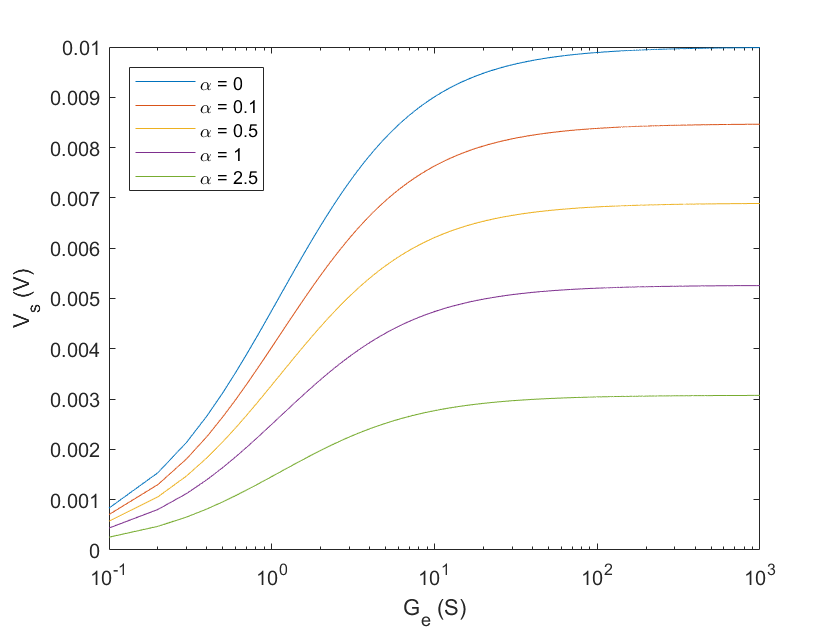

G_i = [0, 0.2, 0.5, 1, 2.5]; %Set the values of G_i in an array
V_s = [];
xval = [];
currentval = 0;
for y = 1:5 %Iterating through each of the G_i values
    indexer = 0; %Reset the index of the matrix when we have a new value of G_i (a new curve)
    for x = 0.1:0.1:1000 %Iterating through all of G_e in 0.1 S steps
        indexer = indexer + 1; 
        xval(indexer) = x; %For plotting the voltage values on the scale of 0.1 S steps
        currentval = (0.1*x)/(9*x*G_i(y) + 10*(x+G_i(y)) + 11); %This is the above equation,
        %                                                       we solve for it at each step
        V_s(y, indexer) = currentval; % Set the appropriate
        %                               part in the array equal to the equation value
    end
end
semilogx(xval,V_s);
legend ('\alpha = 0', '\alpha = 0.1', '\alpha = 0.5', '\alpha = 1', '\alpha = 2.5',...
'Location', 'northwest');
xlabel('G_e (S)');
ylabel('V_s (V)');

5. We can mathematically look at this as such:


$$\begin{array}{l}
V_s =\frac{0\ldotp 1∗G_e }{9∗G_e ∗G_i +10∗\left(G_e +G_i \right)+11}\\
=\frac{{0\ldotp 1∗G}_e }{G_e ∗\left(9∗G_i +10\right)+\left(10∗G_i +11\right)}\text{ }\mathrm{thus}\text{ }\mathrm{we}\text{ }\mathrm{are}\text{ }\mathrm{doing}:\\
\lim_{G_e \to \infty } \frac{{0\ldotp 1∗G}_e }{G_e ∗\left(9∗G_i +10\right)+\left(10∗G_i +11\right)}\\
\text{so}\text{ }\text{as}\text{ }G_e \to \infty ,\text{the}\text{ }\text{second}\text{ }\text{part}\text{ }\text{of}\text{ }\text{the}\text{ }\text{denominator}\to 0\text{ }\text{so}\text{ }\text{we}\text{ }\text{have}:\\
\to \frac{{0\ldotp 1∗G}_e }{\left(9∗G_i +10\right)∗G_e }=\underline{\frac{0\ldotp 1}{9∗G_i +10}} 
\end{array}$$


Thus V_s, as the G_e approaches infinity, is dependent on the level of inhibition. Thus this is a proximal inhibition circuit, which is logical since the plot shows that as we increase the value of G_i, which is the level of inhibition, the voltage will tend to decrease, and this can not be corrected by simply increasing the G_e value. It is not that at larger values of G_e the V_s all tends to the same value - for all values of G_e, the curves which have a higher value of G_i show lower values of V_s. 

## Problem 2: Dendritic Inhibition

- So this can be thought of in the same way as the problem 1 in the earlier section. The current input to a junction must be equal to the current leaving the junction, thus we can write the currents in the dendritic and somatic compartments as such:


$$\begin{array}{l}
\mathrm{Dendritic}\text{ }\mathrm{Compartment}:\\
G^∗ ∗\left(V_s -V_d \right)=G_e ∗\left(V_d -E_e \right)+G_d ∗V_d +{G_i ∗V}_d \\
\mathrm{Somatic}\text{ }\mathrm{Compartment}:\\
G_s ∗\left(-V_s \right)=G^∗ ∗\left(V_s -V_d \right)
\end{array}$$


2. So now we can solve for $V_d$ in each compartment and then set these equal to one another

Dendritic:


$$\begin{array}{l}
G^∗ ∗\left(V_s -V_d \right)=G_e ∗\left(V_d -E_e \right)+G_d ∗V_d +G_i ∗V_d \\
=G^∗ ∗V_s +G^∗ ∗V_d =G_e ∗V_d -G_e ∗E_e +G_d ∗V_d +G_i ∗V_d \\
=G_e ∗V_d +G_i ∗V_d +G_d ∗V_d +G^∗ ∗V_d =G^∗ ∗V_s +G_e ∗V_e \\
=V_d =\frac{\left(G^∗ ∗V_s +G_e ∗V_e \right)}{G_e +G_i +G_d +G^∗ }
\end{array}$$


Somatic:


$$\begin{array}{l}
G^∗ ∗V_s +G_s ∗V_s =G^∗ ∗V_d \\
=V_d =\frac{\left(G^∗ ∗V_s +G_s ∗V_s \right)}{G^∗ }\\
=V_d =\frac{\left(G^∗ +G_s \right)}{G^∗ }∗V_s 
\end{array}$$


Now we can combine the two expressions, in a similar manner as we had stated in Problem 1. We will say that the dendritic equation resembles an equation where $V_d =b∗V_s +c$ and hte somatic compartment resembles an equation where $V_d =a∗V_s$. Thus, setting these expressions equal to one another gives us that, $V_s =\frac{c}{a-b}$ and we have that $a=\frac{\left(G^∗ +G_s \right)}{G^∗ }\text{ }$, $b=\frac{\left(G^∗ \right)}{G_e +G_i +G_d +G^∗ }\text{ }$ and $c=\frac{\left(G_e ∗V_e \right)}{G_e +G_i +G_d +G^∗ }$. So we can say:


$$\begin{array}{l}
V_s =\frac{\left(\frac{\left(G_e ∗V_e \right)}{G_e +G_i +G_d +G^∗ }\right)}{\frac{\left(G^∗ +G_s \right)}{G^∗ }-\frac{G^∗ }{G_e +G_i +G_d +G^∗ }}\\
=\frac{\left(G_e ∗V_e \right)}{\frac{\left(\left(G^∗ +G_s \right)∗\left(G_e +G_i +G_d +G^∗ \right)\right)}{G^∗ }+G^∗ }\\
=\frac{\left(G_e ∗V_e ∗G^∗ \right)}{G_e ∗G^∗ +G_i ∗G^∗ +G_d ∗G^∗ +G^{∗^2 } +G_s ∗G_e +G_s ∗G_i +G_s ∗G_d +G_s ∗G^∗ -G^{∗^2 } }\\
=\frac{\left(G_e ∗V_e ∗G^∗ \right)}{G^∗ ∗G_d +G_d ∗G_s +G^∗ ∗G_s +G_e ∗\left({G^∗ +G}_s \right)+G_i ∗\left(G^∗ {+G}_s \right)}
\end{array}$$


Thus we arrived at the equation that we expect to reach.

3. So the equation can be simplified as such:


$$V_s =\frac{\left(G_e \ast G^\ast  \ast E_e \right)}{G^\ast  \ast G_d +G_d \ast G_s +G^\ast  \ast G_s +G_e \ast \left(G^\ast  +G_s \right)+G_i \ast \left(G^\ast  +G_s \right)}$$


and then when $G_d =G_s$we find


$$V_s =\frac{\left(G_e \ast G^\ast  \ast E_e \right)}{G_d^2 +2\ast G^\ast  \ast G_d +\left(G_e +G_i \right)\ast \left(G^\ast  +G_d \right)}$$


and then $G^∗ =\frac{1}{9}∗G_s =\frac{1}{9}∗G_d$


$$V_s =\frac{\left(G_e \ast \frac{1}{9}\ast G_d \ast E_e \right)}{G_d^2 +\frac{2}{9}\ast G_d^2 +\left(G_e +G_i \right)\ast \left(\frac{10}{9}\ast G_d \right)}$$


but we also know that $G_s =1=G_{d\text{ }}$so we substitute this in


$$\begin{array}{l}
V_s =\frac{\left(\frac{1}{9}\ast G_e \ast E_e \right)}{1+\frac{2}{9}+\frac{10}{9}\ast \left(G_e +G_i \right)}\\
=\frac{\left(G_e \ast E_e \right)}{11+10\ast \left(G_e +G_i \right)}
\end{array}$$


we can say that $E_e =0\ldotp 1\text{ }V$and substitute this in:


$$V_s =\frac{\left(0\ldotp 1\ast G_e \right)}{11+10\ast \left(G_e +G_i \right)}$$



$$\begin{array}{l}
\mathrm{Finally},\alpha =\frac{G_i }{G_d }\text{ }\mathrm{so}\text{ }G_i =\alpha \ast G_d =\alpha \text{ }\mathrm{since}\text{ }G_d =1,\mathrm{thus}:\\
V_s =\frac{\left(0\ldotp 1\ast G_e \right)}{11+10\ast \left(G_e +\alpha \right)}
\end{array}$$


4. We can graph the above equation as such:

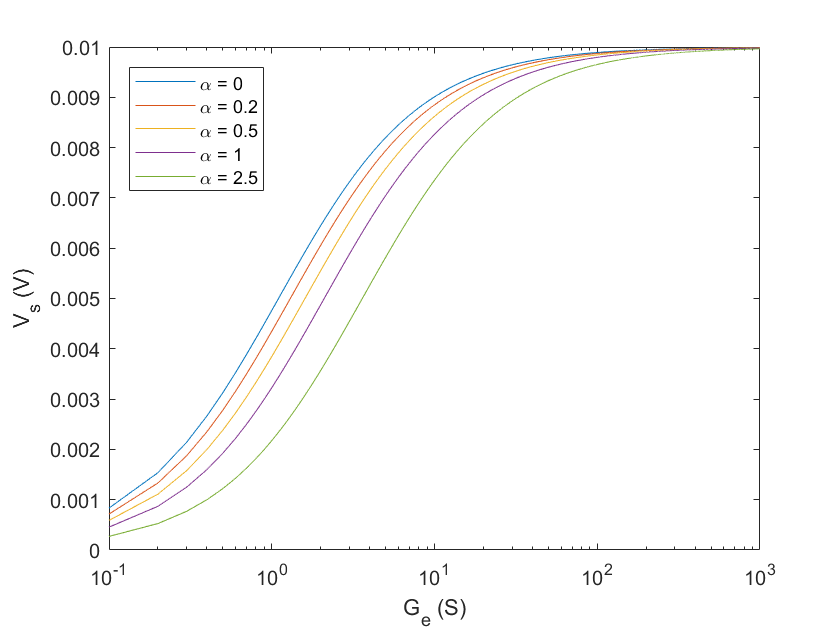

alpha2 = [0, 0.2, 0.5, 1, 2.5]; %Set the values of G_i in an array
V_s2 = [];
xval2 = [];
currentval2 = 0;
for n = 1:5 %Iterating through each of the G_i values
    indexer2 = 0; %Reset the index of the matrix when we have a new value of G_i (a new curve)
    for m = 0.1:0.1:1000 %Iterating through all of G_e in 0.1 S steps
        indexer2 = indexer2 + 1; 
        xval2(indexer2) = m; %For plotting the voltage values on the scale of 0.1 S steps
        currentval2 = (0.1*m)/(11+10*(m+alpha2(n))); %This is the above equation,
        %                                             we solve for it at each step
        V_s2(n,indexer2) = currentval2; % Set the appropriate
        %                                  part in the array equal to the equation 
    end
end
semilogx(xval2,V_s2);
legend('\alpha = 0', '\alpha = 0.2', '\alpha = 0.5', '\alpha = 1', '\alpha = 2.5', ...
'Location', 'northwest');
xlabel('G_e (S)');
ylabel('V_s (V)');

5. We can mathematically look at this as such:


$$\lim_{G_e \to \infty } \frac{\left(0\ldotp 1\ast G_e \right)}{11+10\ast \left(G_e +\alpha \right)}=\frac{\left(0\ldotp 1\ast G_e \right)}{10\ast \left(G_e \right)}\text{ }$$


the constant term in the denominator (11) and the alpha both are relatively small as G_e approaches infinity. this simplifies to:


$$V_s =\frac{\left(0\ldotp 1\right)}{10}=\ldotp 01\text{ }V$$


In this expression, V_s is independent of inhibition as G_e approaches infinity (it will always approach 0.01 V), which is what we would expect from looking at our graph. We see on our graph that at high values of G_e, the curves are all roughly the same value, independent of their alpha value (amount of inhibition), despite being slightly different values of V_s at lower values of G_e.  This is dendritic, distal inhibition.